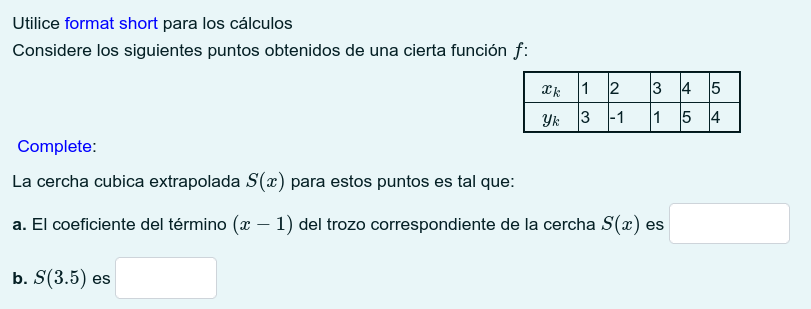


xx = [1 2 3 4 5]

xx =      1     2     3     4     5



yy = [3 -1 1 5 4]

yy =      3    -1     1     5     4


 
S=csextrapolado(xx,yy) % S esta organizado de menor a mayor

S =   -0.541666666666667   4.625000000000000  -8.083333333333332   3.000000000000000
  -0.541666666666667   3.000000000000000  -0.458333333333333  -1.000000000000000
  -1.291666666666667   1.375000000000000   3.916666666666667   1.000000000000000
  -1.291666666666667  -2.500000000000000   2.791666666666667   5.000000000000000


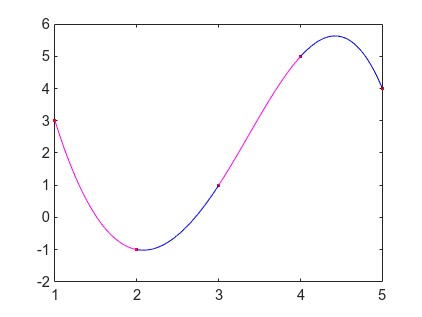


GraficaCercha(xx,yy,S);

a = S(1, :);

%%%%%%%%%%%%%%%%%% Ahora para aproximar 3.5

% Tomamos la fila 3 que corresponde al intervalo [3,4] y evalumos
% recordando restar x_i = (3)
polyval(S(3,:),3.5-3)

ans =    3.140625000000000


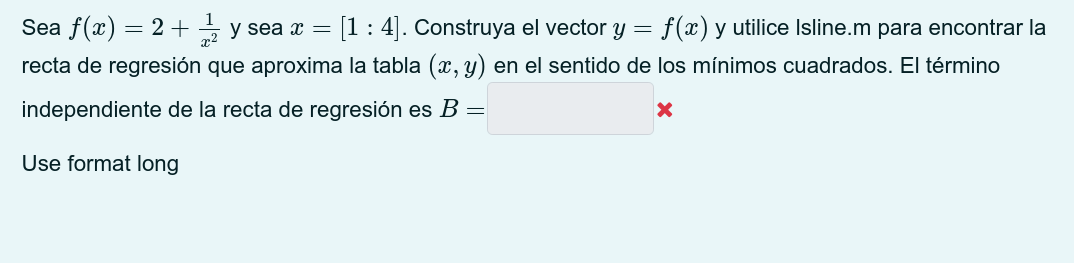

clear
format long


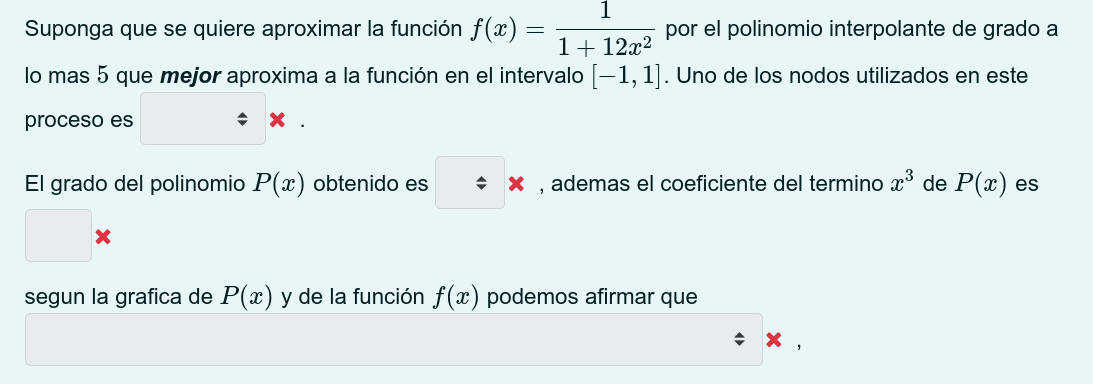

format short
clear 
clf
syms f(x)

f(x) = 1/(1+12*x^2)

$$f(x) = \frac{1}{12\,x^{2}+1}$$


% Como nos piden la mejor aproximacion utilicemos nodos de cehvycheb

[C, X, Y] = cheby (f, 5, -1, 1)

C =     0.2597   -0.0000   -0.2727    0.0000    0.1169   -0.0000


X =     0.9659    0.7071    0.2588   -0.2588   -0.7071   -0.9659


$$Y = \left(\begin{array}{cccccc} \frac{20282409603651670423947251286016}{247367359025904589499277044156203} & \frac{1}{7} & \frac{5070602400912917605986812821504}{9146593856304708375523191332107} & \frac{20282409603651670423947251286016}{36586375425218791539867982444819} & \frac{1}{7} & \frac{1267650600228229401496703205376}{15460459939119033581097421752523} \end{array}\right)$$

X = double(X)

X =     0.9659    0.7071    0.2588   -0.2588   -0.7071   -0.9659


Y = double(Y)

Y =     0.0820    0.1429    0.5544    0.5544    0.1429    0.0820




xx = linspace(-1,1,1000)

xx =    -1.0000   -0.9980   -0.9960   -0.9940   -0.9920   -0.9900   -0.9880   -0.9860   -0.9840   -0.9820   -0.9800   -0.9780   -0.9760   -0.9740   -0.9720   -0.9700   -0.9680   -0.9660   -0.9640   -0.9620   -0.9600   -0.9580   -0.9560   -0.9540   -0.9520   -0.9499   -0.9479   -0.9459   -0.9439   -0.9419   -0.9399   -0.9379   -0.9359   -0.9339   -0.9319   -0.9299   -0.9279   -0.9259   -0.9239   -0.9219   -0.9199   -0.9179   -0.9159   -0.9139   -0.9119   -0.9099   -0.9079   -0.9059   -0.9039   -0.9019


yy = polyval(C,xx)

yy =    -0.1039   -0.1027   -0.1015   -0.1004   -0.0992   -0.0981   -0.0970   -0.0959   -0.0948   -0.0937   -0.0926   -0.0916   -0.0905   -0.0895   -0.0885   -0.0875   -0.0865   -0.0855   -0.0846   -0.0836   -0.0827   -0.0818   -0.0808   -0.0799   -0.0790   -0.0782   -0.0773   -0.0764   -0.0756   -0.0748   -0.0739   -0.0731   -0.0723   -0.0715   -0.0708   -0.0700   -0.0692   -0.0685   -0.0678   -0.0670   -0.0663   -0.0656   -0.0649   -0.0642   -0.0636   -0.0629   -0.0622   -0.0616   -0.0610   -0.0603


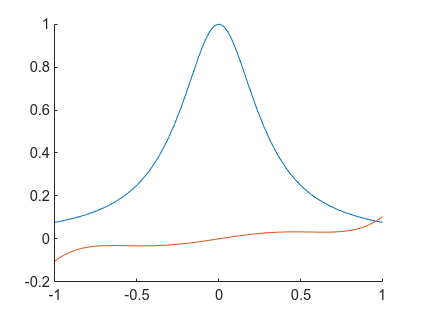


hold on
fplot(f)
plot(xx,yy)
xlim([-1 1])

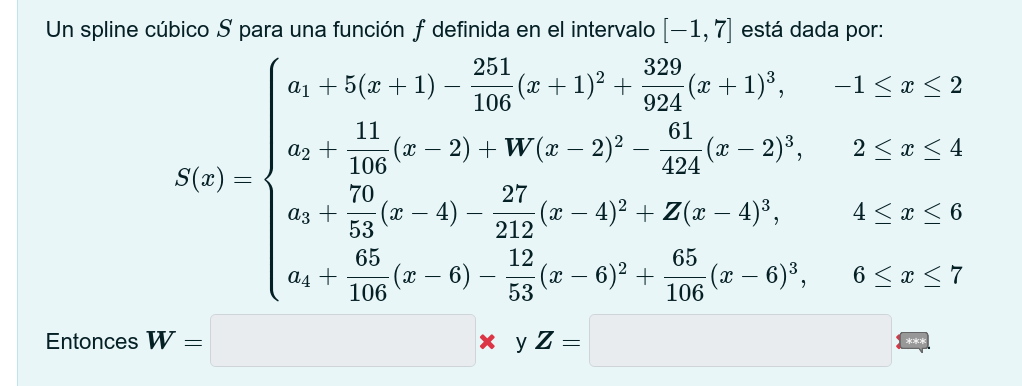

format long
clear
clf
syms f2(x) 
syms f1(x) 
syms Z W
f2(x) = -2*(27/212)+(2*3*Z*2) == -2*(12/53)

$$f2(x) = 12\,Z-\frac{27}{106}=-\frac{24}{53}$$


Z = double(solve(f2))

Z =   -0.016509433962264




f1(W) = 2* W - (2*3*(61/424)*2) == -2*(27/212)

$$f1(W) = 2\,W-\frac{183}{106}=-\frac{27}{106}$$


W = double(solve(f1))

W =    0.735849056603774


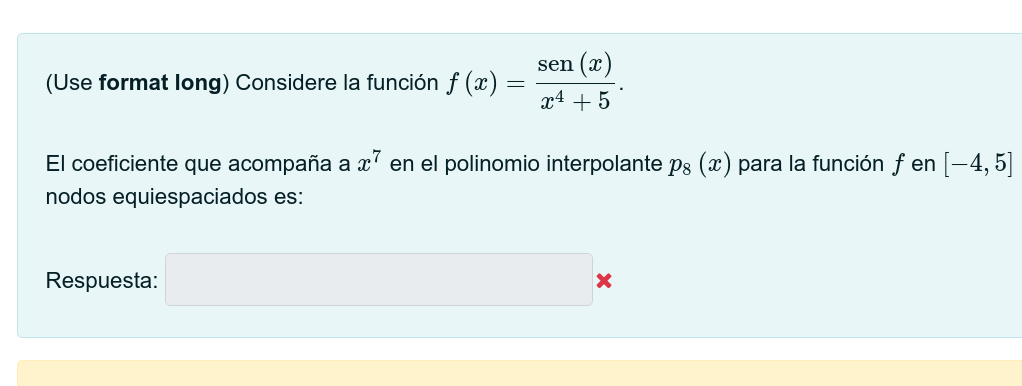

format long

syms f(x)

f(x) = sin(x)/(x^4 + 5)

$$f(x) = \frac{\sin\left(x\right)}{x^{4}+5}$$


xx = linspace(-4,5,9)

xx =   -4.000000000000000  -2.875000000000000  -1.750000000000000  -0.625000000000000   0.500000000000000   1.625000000000000   2.750000000000000   3.875000000000000   5.000000000000000



yy = f(xx)

$$yy = \left(\begin{array}{ccccccccc} -\frac{\sin\left(4\right)}{261} & -\frac{4096\,\sin\left(\frac{23}{8}\right)}{300321} & -\frac{256\,\sin\left(\frac{7}{4}\right)}{3681} & -\frac{4096\,\sin\left(\frac{5}{8}\right)}{21105} & \frac{16\,\sin\left(\frac{1}{2}\right)}{81} & \frac{4096\,\sin\left(\frac{13}{8}\right)}{49041} & \frac{256\,\sin\left(\frac{11}{4}\right)}{15921} & \frac{4096\,\sin\left(\frac{31}{8}\right)}{944001} & \frac{\sin\left(5\right)}{630} \end{array}\right)$$


[C, L] = lagran (xx,yy)

L =    0.000009666278351  -0.000082163365987   0.000048633462956   0.000988527997031  -0.001577828786438  -0.002688543403289   0.004462527756797   0.001207746065874  -0.001315870002941
  -0.000077330226811   0.000570310422733   0.000600517542581  -0.011190982725748   0.013163809723032   0.034152915438605  -0.047856465035111  -0.014875519768541   0.014646205250131
   0.000270655793840  -0.001691598711497  -0.004880262282669   0.041666190762564  -0.006379904187256  -0.240831207045428   0.245288528351426   0.104365073990705  -0.084215680188251
  -0.000541311587679   0.002774221886855   0.013947231376294  -0.074968483145970  -0.086216557328231   0.557877427076398   0.003658776033397  -1.069526732232275   0.471607809054208
   0.000676639484599  -0.002706557938395  -0.020954679038671   0.072336989900397   0.202508319068277  -0.528735938898678  -0.704783179394521   0.981658406816992   0.736887201647200
  -0.000541311587679   0.001556270814577   0.018210060129267  -0.036660115825728  -0.192644


double(C)

ans =    0.000064056873307  -0.000331128313723  -0.001780313763408   0.009547009962148   0.013882371508637  -0.081192877046434  -0.029837280717607   0.208009603736152   0.007169130740720



% Tener muy presente que los coeficientes de los polinomios
% Estan de mayor a menor

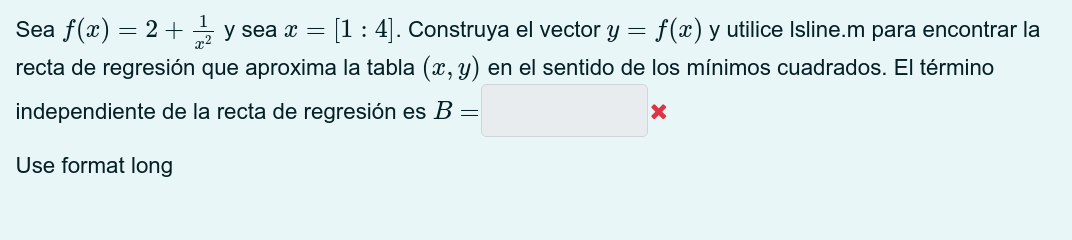

clear
format long
syms f(x)

f(x) = 2 + (1/x^2)

$$f(x) = \frac{1}{x^{2}}+2$$

X = [1:4]

X =      1     2     3     4


Y = f(X)

$$Y = \left(\begin{array}{cccc} 3 & \frac{9}{4} & \frac{19}{9} & \frac{33}{16} \end{array}\right)$$


[A, B] = lsline (X, Y)

$$A = -\frac{85}{288}$$

$$B = \frac{99}{32}$$

double([A, B])

ans =   -0.295138888888889   3.093750000000000
